# Лабораторная работа 1

## Задание 1

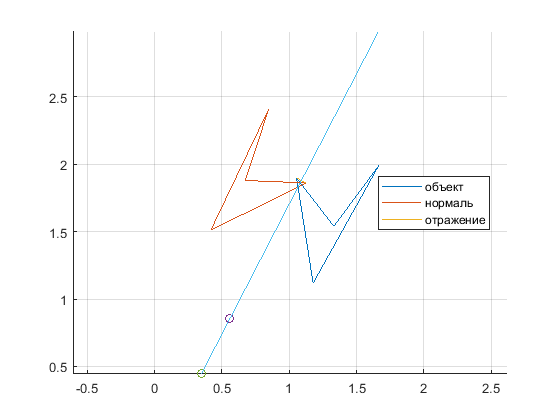

K = rand(1,2);
L = rand(1,2);
l = L-K;
A = -l(2);
B = l(1);
C = K(1)*L(2) - K(2)*L(1);

X = 1+rand(1,4);
Y = 1+rand(1,4   );
X = cat(2, X, X(1));
Y = cat(2, Y, Y(1));
Q = [1-2*A^2/(A^2+B^2), -2*A*B/(A^2 + B^2), -2*A*C/(A^2 + B^2);
    -2*A*B/(A^2 + B^2),  1-2*B^2/(A^2+B^2), -2*B*C/(A^2 + B^2);
                     0,                  0,                 1];                 
tmp = Q*[X; Y; ones(1,length(X))];
X_ = tmp(1,:)./tmp(3, :);
Y_ = tmp(2,:)./tmp(3, :);
figure
axis equal
hold on
grid on
plot(X, Y)
plot(X_,Y_)
for i =1:1:1
    plot([X(i), X_(i)], [Y(i), Y_(i)])
end
plot(K(1),K(2),'o')
plot(L(1),L(2),'o')
t = cat(2,[K(1),L(1)],cat(2,X,X_));
plot([min(t), max(t)], [(-C-A*min(t))/B, (-C-A*max(t))/B])
legend('объект','нормаль','отражение','location','best')

## Задание 2

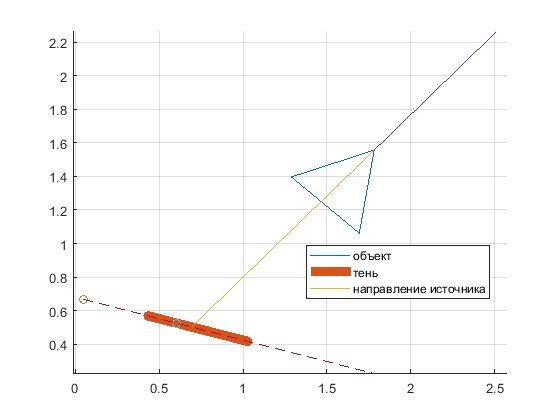

K = rand(1,2);
L = rand(1,2);
light = rand(1,2);
l = L-K;
A = -l(2);
B = l(1);
C = K(1)*L(2) - K(2)*L(1);
n = [A,B];
X = 1+rand(1,3);
Y = 1+rand(1,3);
X = cat(2, X, X(1));
Y = cat(2, Y, Y(1));
z = dot(n,light);
Q = [1-A*light(1)/z,  -B*light(1)/z, -C*light(1)/z;
      -A*light(2)/z, 1-B*light(2)/z, -C*light(2)/z;
                  0,              0,             1];                 
tmp = Q*[X; Y; ones(1,length(X))];
X_ = tmp(1,:)./tmp(3, :);
Y_ = tmp(2,:)./tmp(3, :);
figure
axis equal
hold on
grid on
plot(X, Y)
plot(X_,Y_,'linewidth',7)
plot([X(1),X_(1)],[Y(1),Y_(1)])
plot([X(1), X(1)+light(1)], [Y(1),Y(1)+light(2)])
plot(K(1),K(2),'o')
plot(L(1),L(2),'o')
t = cat(2,[K(1),L(1)],cat(2,X,X_));
plot([min(t), max(t)], [(-C-A*min(t))/B, (-C-A*max(t))/B],'--')
legend('объект','тень','направление источника','location','best')

## Задание 3

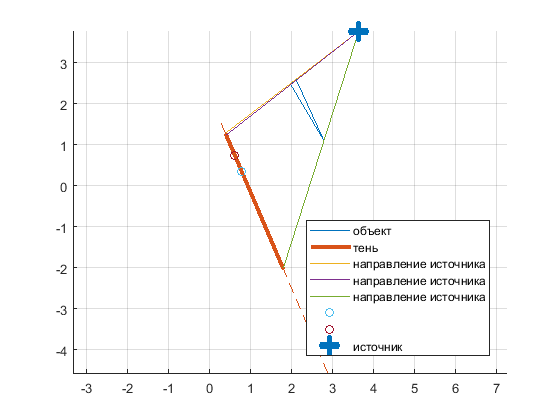

K = rand(1,2);
L = rand(1,2);
S = 3+6*rand(1,2);
l = L-K;
A = -l(2);
B = l(1);
C = K(1)*L(2) - K(2)*L(1);
n = [A,B];
X = 1+2*rand(1,3);
Y = 1+2*rand(1,3);
X = cat(2, X, X(1));
Y = cat(2, Y, Y(1));
z = dot(n,S);
Q = [A*S(1)-C-z,     B*S(1), C*S(1);
         A*S(2), B*S(2)-C-z, C*S(2);
              A,          B,     -z];                 
tmp = Q*[X; Y; ones(1,length(X))];
X_ = tmp(1,:)./tmp(3, :);
Y_ = tmp(2,:)./tmp(3, :);
figure
axis equal
hold on
grid on
plot(X, Y)
plot(X_,Y_,'linewidth',3)
plot([S(1), X_(1)], [S(2),Y_(1)])
plot([S(1), X_(2)], [S(2),Y_(2)])
plot([S(1), X_(3)], [S(2),Y_(3)])
plot(K(1),K(2),'o')
plot(L(1),L(2),'o')
plot([S(1)],[S(2)],'o','linewidth', 10)
t = cat(2,[K(1),L(1)],cat(2,X,X_));
plot([min(t)-0.1, max(t)+0.1], [(-C-A*(min(t)-0.1))/B, (-C-A*(max(t)+0.1))/B],'--')
legend('объект','тень','направление источника','направление источника','направление источника', '','','источник', 'location','best')